# **Tips for Training Neural Networks**

## 1. Data Preprocessing

Neural networks tend to learn best when all inputs and outputs have similar magnitudes. 

If your data does not satisfy this condition, it may be necessary to rescale or offset certain features in the dataset. 

For example, let's consider the task of approximating the following function: 

                                $f\left(x_1 ,x_2 \right)=x_1^2 +{0\ldotp 01x}_2^2$ , $x_1 \in \left\lbrack -2,2\right\rbrack ,x_{2\;} \in \left\lbrack -100,100\right\rbrack$

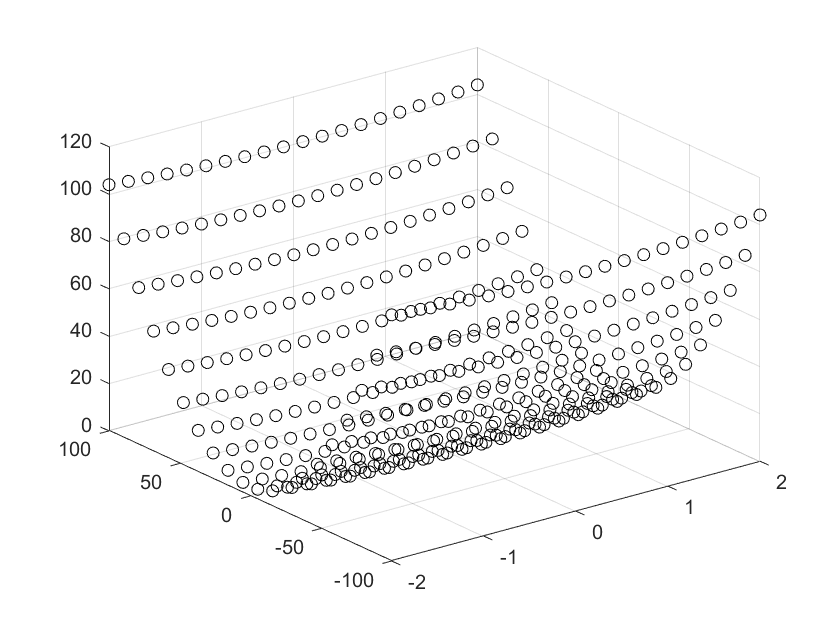

% Generate Data and Labels for Fitting
clear; clc;
n=20;
x1=linspace(-2,2,n);
x2=linspace(-100,100,n);
counter=0;
for i=1:n
    for j=1:n
        counter=counter+1;
        data(1,counter)=x1(i);
        data(2,counter)=x2(j);
        label(counter)=x1(i)^2+0.01*x2(j)^2;
    end
end
% Visualize Data
scatter3(data(1,:),data(2,:),label,'black')

This dataset does not satisfy the aforementioned condition. If you try to fit the surface directly, 

you will find that it is challenging for neural networks to approximate it. 

This is because the minimization problem posed by this dataset is difficult to solve. 

Therefore, **it is crucial for users to perform data preprocessing before optimization.**

If you are not familiar with preprocessing methods, the package provides a fundamental technique: normalization.

                                                       
$$\hat{x_1 } =\frac{x_1 -\mu_1 }{\sigma_1 },\hat{x_2 } =\frac{x_2 -\mu_2 }{\sigma_2 }$$


where $\mu {\;}_1 ,\mu_{2\;} ,\sigma {\;}_1 ,\sigma {\;}_2$ are mean and standard deviation of $x_1$ and $x_2$.

Use the following command, and the package will automatically handle the normalization process.

NN.InputAutoScaling='on';

You can try disabling autoscaling (`NN.InputAutoScaling='off'`) and observe the training results. 

Start Optimizing

% Define Structure
InputDimension=2; OutputDimension=1;
LayerStruct=[InputDimension,5,10,OutputDimension];
NN=Initialization(LayerStruct,NN);
% Solver Set Up
option.Solver='Auto';
option.MaxIteration=500;
NN=OptimizationSolver(data,label,NN,option);

Iteration : 6 , Cost :    2351.93588771 
Iteration : 12 , Cost :    2256.40896867 
Iteration : 18 , Cost :    2171.60961977 
Iteration : 24 , Cost :    2093.87485386 
Iteration : 30 , Cost :    2021.37667152 
Iteration : 36 , Cost :    1953.48217441 
Iteration : 42 , Cost :    1889.86778698 
Iteration : 48 , Cost :    1829.76964848 
Iteration : 54 , Cost :    1772.67726805 
Iteration : 60 , Cost :    1715.39393049 
Iteration : 66 , Cost :    1656.27820360 
Iteration : 72 , Cost :    1597.85395420 
Iteration : 78 , Cost :    1541.06180739 
Iteration : 84 , Cost :    1486.62666685 
Iteration : 90 , Cost :    1434.14238571 
Iteration : 96 , Cost :    1383.65538393 
Iteration : 102 , Cost :    1335.35799669 
Iteration : 108 , Cost :    1288.47700765 
Iteration : 114 , Cost :    1243.85064498 
Iteration : 120 , Cost :    1200.80885056 
------------------------------------------------------
First Stage Optimization Finished in  125  Iteration.
------------------------------------------------

Visualize & Quatify Fitting Performance

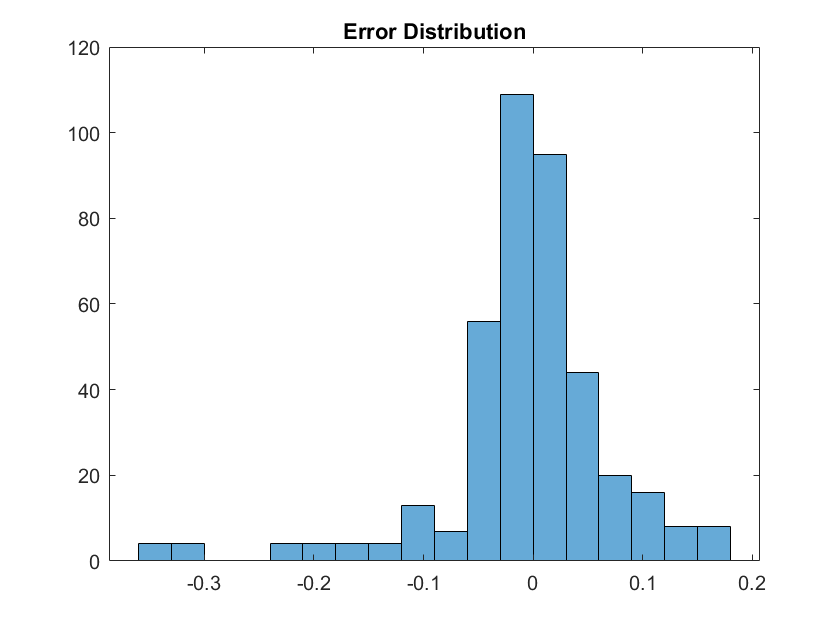

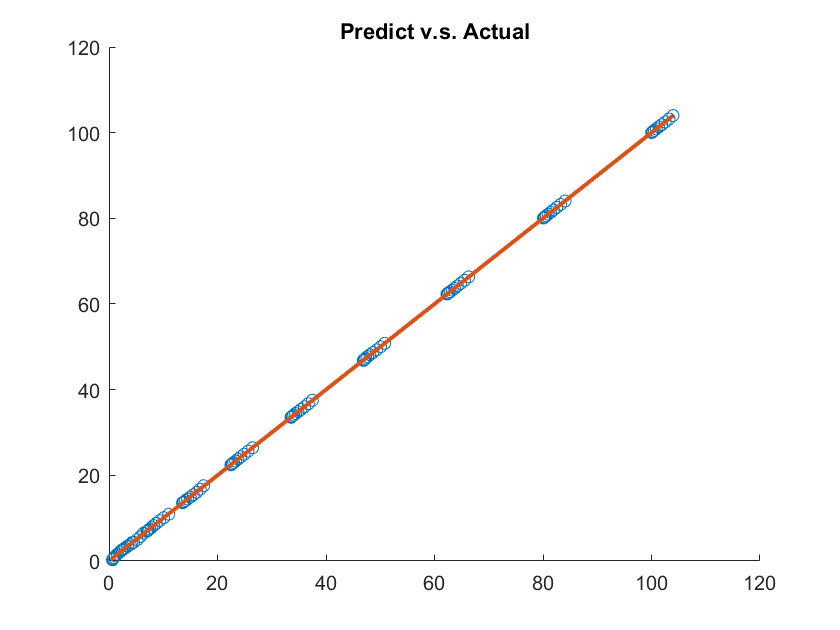

Report=FittingReport(data,label,NN);

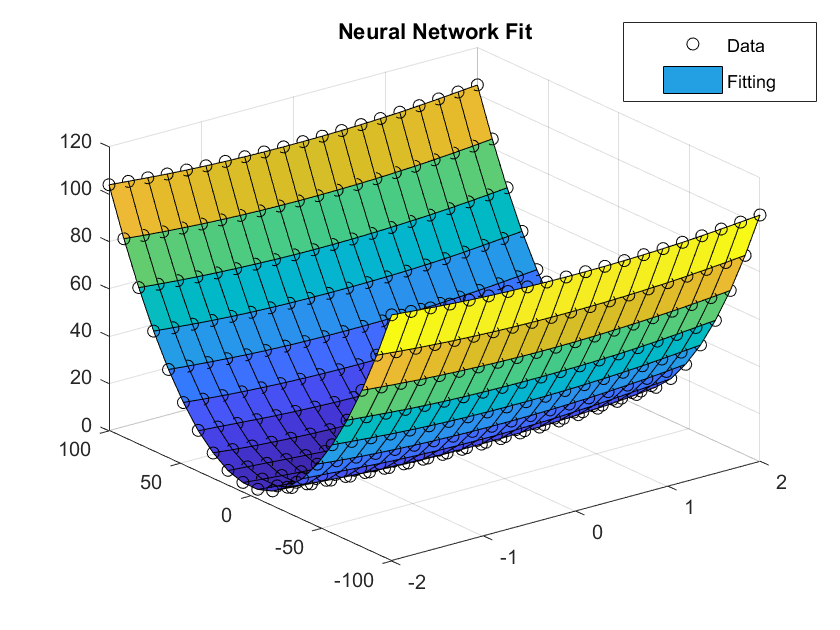


prediction=NN.Evaluate(data);
figure
scatter3(data(1,:),data(2,:),label,'black')
hold on
[X,Y]=meshgrid(x1,x2);
n1=numel(x1); n2=numel(x2);
surf(X,Y,reshape(prediction,n1,n2))
title('Neural Network Fit')
legend('Data','Fitting')
legend("Position", [0.74111,0.83804,0.23204,0.12684])

## 2. Pay Attention to the Scale of Label

If all the label values are very close to the mean value, it can make the neural network difficult to train.

This situation often occurs in physics-related data. Take the following function as an example :

                                        
$$f\left(x\right)=1+0\ldotp 001\sin \left(x\right),x\in \left\lbrack 0,2\pi \;\right\rbrack$$


clear;
n=200;
data=linspace(0,2*pi,n);
label=1+0.001*sin(data);

In such cases, the neural network tends to learn only the mean value of the labels. To address this, a simple solution is to normalize the labels using the following command:

NN.LabelAutoScaling='on';

Set up NN structure and solver

% Define Structure
InputDimension=1; OutputDimension=1;
LayerStruct=[InputDimension,3,4,OutputDimension];
NN=Initialization(LayerStruct,NN);
% Solver Set Up
option.Solver='Auto';
option.MaxIteration=500;
NN=OptimizationSolver(data,label,NN,option);

Iteration : 6 , Cost :       1.05262336 
Iteration : 12 , Cost :       0.91641835 
Iteration : 18 , Cost :       0.76878304 
Iteration : 24 , Cost :       0.57995532 
Iteration : 30 , Cost :       0.43308644 
Iteration : 36 , Cost :       0.33141947 
Iteration : 42 , Cost :       0.25660428 
Iteration : 48 , Cost :       0.20314016 
Iteration : 54 , Cost :       0.16713607 
Iteration : 60 , Cost :       0.14531201 
Iteration : 66 , Cost :       0.13125939 
Iteration : 72 , Cost :       0.11951090 
Iteration : 78 , Cost :       0.10463097 
Iteration : 84 , Cost :       0.08329658 
Iteration : 90 , Cost :       0.06714766 
Iteration : 96 , Cost :       0.05685056 
Iteration : 102 , Cost :       0.04852369 
Iteration : 108 , Cost :       0.04141664 
Iteration : 114 , Cost :       0.03546478 
Iteration : 120 , Cost :       0.03045429 
------------------------------------------------------
First Stage Optimization Finished in  125  Iteration.
------------------------------------------------

Visualize & Quatify Fitting Performance

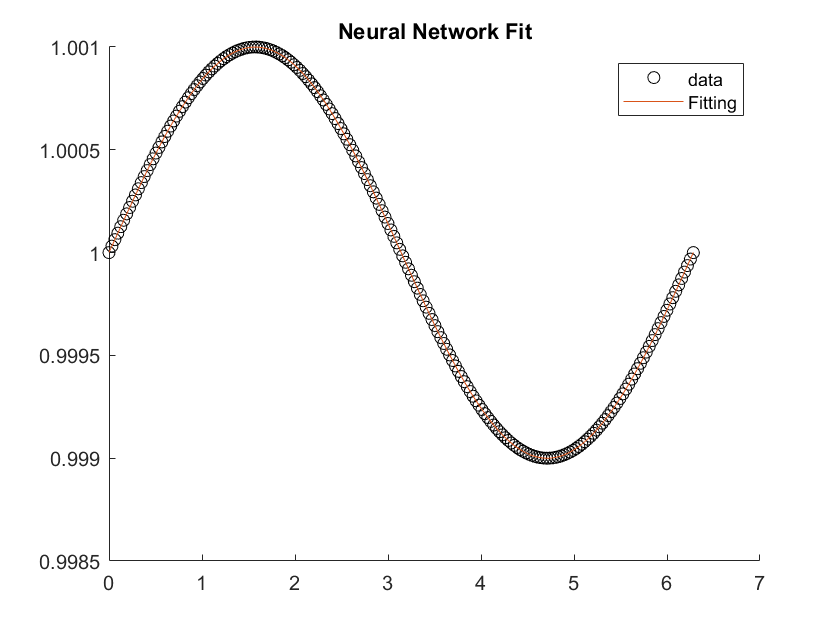

prediction=NN.Evaluate(data);
figure
scatter(data,label,'black')
hold on
plot(data,prediction)
title('Neural Network Fit')
legend('data','Fitting')

Finally, after applying `NN.InputAutoScaling` or `NN.LabelAutoScaling`, the `NN.Evaluate` function 

will also consider the autoscaling transformation. Therefore, **when using the trained neural network**

** for evaluation, there is no need to revert the data or labels to their original scale. **

**You can directly use the original data with the **`NN.Evaluate`** function to obtain results in the correct scale.**

## **3. Training Deep Neural Networks**

If you have a complex problem that requires a deeper neural network to learn effectively, 

it is recommended to use `'``ResNet'`. This type of neural network addresses the issue of 

vanishing gradients, making it possible to train very deep neural nets.